lobal pt1 pt06 pt03 pt01 pt003 
load("experimental_data.mat")

warning('off')
x0_ =[0.0000    2.1474   40.0000    0.0799    0.6025   60.0000    1.1583    0.0032    3.5302   25.0000   36.9446];

MU  = x0_(1);
ALPHA = x0_(2);
KELAS = x0_(3);
MUVIS = x0_(4);
ALPHAVIS = x0_(5);
KVIS = x0_(6);
RTIME = x0_(7);
MUVIS_2 = x0_(8);
ALPHAVIS_2 = x0_(9);
KVIS_2 = x0_(10);
RTIME_2 = x0_(11);
% 
x0=[MU, ALPHA, KELAS, MUVIS, ALPHAVIS, KVIS, RTIME, MUVIS_2, ALPHAVIS_2, KVIS_2, RTIME_2];
global xsol
xsol = zeros(size(x0));
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-Inf, -Inf, 0, -Inf, -Inf, 0, 0, -Inf, -Inf, 0, 0];
ub = [];
nonlcon = [];
penalty = 1e10;
f1 = @loss_function_lsq_2EL;
f2 = @constraint2EL;
loss_function_lsq_cstr = @(x) f1(x) + penalty * f2(x);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         12         33405.7                      1.02e+07
     1         24         12.8345        0.49508       5.83e+04      
     2         36         12.8345       0.378935       5.83e+04      
     3         48         12.8345      0.0947338       5.83e+04      
     4         60         11.2316      0.0236835       1.85e+04      
     5         72         10.0474      0.0473669       3.37e+04      
     6         84         10.0474      0.0473669       3.37e+04      
     7         96         9.54611      0.0118417          9e+03      
     8        108         9.54611      0.0236835          9e+03      
     9        120         9.24333     0.00592086       1.03e+04      
    10        132          9.2222      0.0118417       2.33e+03      
    11        144         9.16155     0.00296043       3.11e+03      
    12        156         9.1383

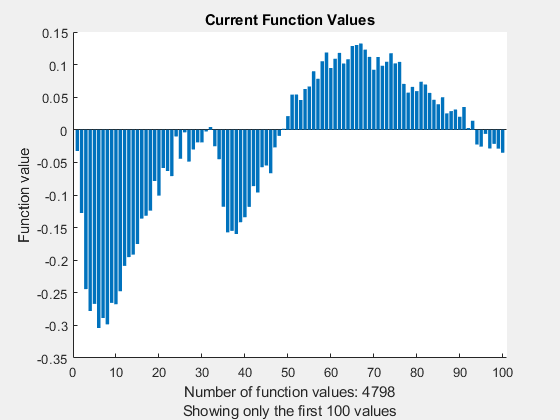


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x =     0.0040    2.1473   40.0000    0.0902    0.4448   59.9981    1.3077    0.0017    3.5307   25.0000   36.8532


fval = 6.1178

exitflag =    -0.0324
   -0.1276
   -0.2443
   -0.2780
   -0.2669
   -0.3039
   -0.2887
   -0.2984
   -0.2654
   -0.2676


output = 3

options = optimset('PlotFcns',@optimplotfval, 'MaxIter', 100, 'Display','iter');
% [x,fval,exitflag,output] = fminsearch(loss_function_cstr, x0, options)
[x,fval,exitflag,output] = lsqnonlin(loss_function_lsq_cstr, x0, lb, ub, options)


MU  = x(1);
ALPHA = x(2);
KELAS = x(3);
MUVIS = x(4);
ALPHAVIS = x(5);
KVIS = x(6);
RTIME = x(7);
ETADEV = RTIME * MUVIS * ALPHAVIS;
ETAVOL = RTIME * KVIS;
MUVIS_2 = x(8);
ALPHAVIS_2 = x(9);
KVIS_2 = x(10);
RTIME_2 = x(11);
ETADEV_2 = RTIME_2 * MUVIS_2 * ALPHAVIS_2;
ETAVOL_2 = RTIME_2 * KVIS_2;


% loss for strain rate pt1
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(12,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;


lenpt1 = size(pt1);
lenpt1 = lenpt1(1);
pt1sim = zeros(lenpt1, 2);
pt1sim(1,:) = [1, 0];
for datapoint = 2:lenpt1
    STRETCH_OLD = pt1(datapoint-1, 2);
    STRETCH_NEW = pt1(datapoint, 2);
    DTIME = pt1(datapoint, 4) - pt1(datapoint-1, 4);


    DFGRD0(1,1) = STRETCH_OLD;
    DFGRD0(2,2) = STRETCH_OLD^(-.5);
    DFGRD0(3,3) = STRETCH_OLD^(-.5);

    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_NEW^(-.5);
    DFGRD1(3,3) = STRETCH_NEW^(-.5);
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                             MU, ALPHA, KELAS, ...
                                                             MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                             MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);
    pt1sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end


% loss for strain rate pt06
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(12,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
lenpt06 = size(pt06);
lenpt06 = lenpt06(1);
pt06sim = zeros(lenpt06, 2);
pt06sim(1,:) = [1, 0];
for datapoint = 2:lenpt06
    STRETCH_OLD = pt06(datapoint-1, 2);
    STRETCH_NEW = pt06(datapoint, 2);
    DTIME = pt06(datapoint, 4) - pt06(datapoint-1, 4);


    DFGRD0(1,1) = STRETCH_OLD;
    DFGRD0(2,2) = STRETCH_OLD^(-.5);
    DFGRD0(3,3) = STRETCH_OLD^(-.5);

    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_NEW^(-.5);
    DFGRD1(3,3) = STRETCH_NEW^(-.5);
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                             MU, ALPHA, KELAS, ...
                                                             MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                             MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);
    pt06sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end


 
% loss for strain rate pt1
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(12,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;

lenpt03 = size(pt03);
lenpt03 = lenpt03(1);
pt03sim = zeros(lenpt03, 2);
pt03sim(1,:) = [1, 0];
for datapoint = 2:lenpt03
    STRETCH_OLD = pt03(datapoint-1, 2);
    STRETCH_NEW = pt03(datapoint, 2);
    DTIME = pt03(datapoint, 4) - pt03(datapoint-1, 4);


    DFGRD0(1,1) = STRETCH_OLD;
    DFGRD0(2,2) = STRETCH_OLD^(-.5);
    DFGRD0(3,3) = STRETCH_OLD^(-.5);

    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_NEW^(-.5);
    DFGRD1(3,3) = STRETCH_NEW^(-.5);
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                             MU, ALPHA, KELAS, ...
                                                             MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                             MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);
    pt03sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end


% loss for strain rate pt01
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(12,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
pt01sim = [1, 0];

lenpt01 = size(pt01);
lenpt01 = lenpt01(1);
for datapoint = 2:lenpt01
    STRETCH_OLD = pt01(datapoint-1, 2);
    STRETCH_NEW = pt01(datapoint, 2);
    DTIME = pt01(datapoint, 4) - pt01(datapoint-1, 4);


    DFGRD0(1,1) = STRETCH_OLD;
    DFGRD0(2,2) = STRETCH_OLD^(-.5);
    DFGRD0(3,3) = STRETCH_OLD^(-.5);

    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_NEW^(-.5);
    DFGRD1(3,3) = STRETCH_NEW^(-.5);
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                             MU, ALPHA, KELAS, ...
                                                             MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                             MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);
    pt01sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end


% loss for strain rate pt003
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(12,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
pt003sim = [1, 0];

lenpt003 = size(pt003);
lenpt003 = lenpt003(1);
for datapoint = 2:lenpt003
    STRETCH_OLD = pt003(datapoint-1, 2);
    STRETCH_NEW = pt003(datapoint, 2);
    DTIME = pt003(datapoint, 4) - pt003(datapoint-1, 4);


    DFGRD0(1,1) = STRETCH_OLD;
    DFGRD0(2,2) = STRETCH_OLD^(-.5);
    DFGRD0(3,3) = STRETCH_OLD^(-.5);

    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_NEW^(-.5);
    DFGRD1(3,3) = STRETCH_NEW^(-.5);
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                             MU, ALPHA, KELAS, ...
                                                             MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                             MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);
    pt003sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

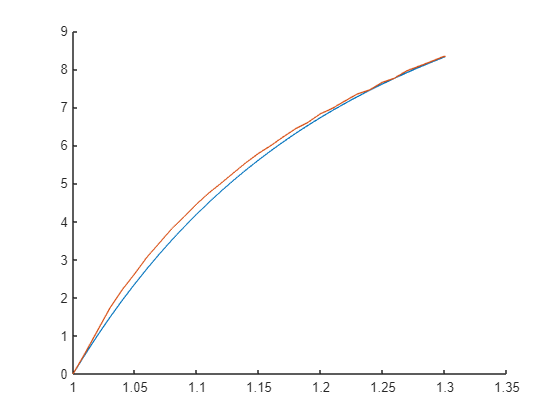

close all
hold on
plot(pt1sim(:,1), pt1sim(:,2));
plot(pt1(:,2), pt1(:,1));
hold off

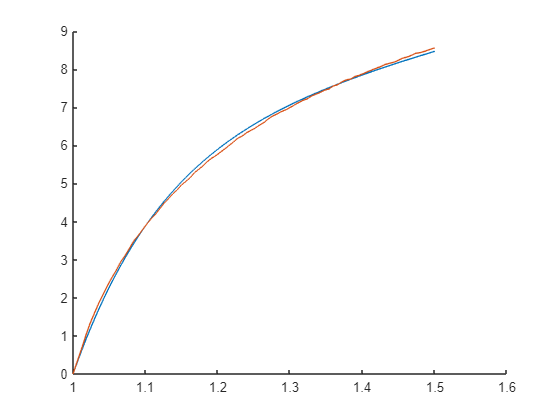

close all
hold on
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt06(:,2), pt06(:,1));
hold off

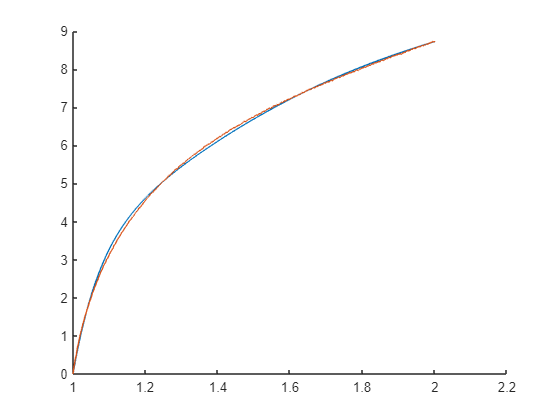

close all
hold on
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt03(:,2), pt03(:,1));
hold off

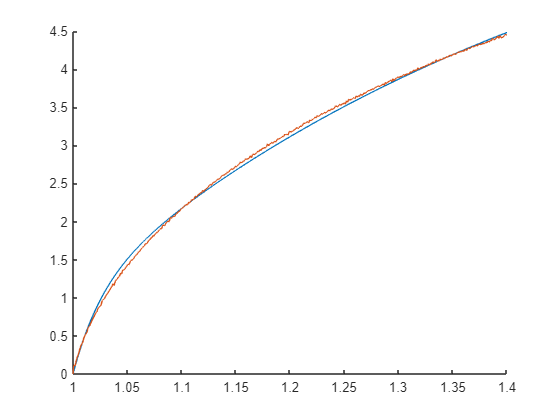

close all
hold on
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt01(:,2), pt01(:,1));
xlim([1, 1.4])
hold off

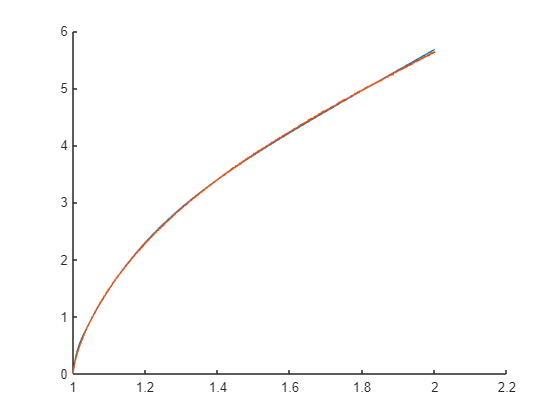

close all
hold on
plot(pt003sim(:,1), pt003sim(:,2));
plot(pt003(:,2), pt003(:,1));
hold off

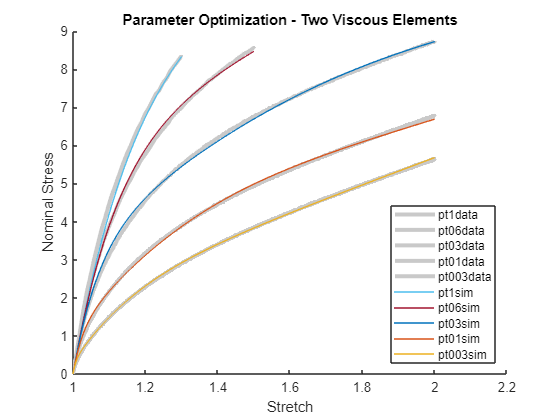

close all
hold on
plot(pt1(:,2), pt1(:,1),'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt06(:,2), pt06(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt03(:,2), pt03(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt01(:,2), pt01(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt003(:,2), pt003(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);

plot(pt1sim(:,1), pt1sim(:,2));
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt003sim(:,1), pt003sim(:,2));
legend('pt1data', 'pt06data', 'pt03data', 'pt01data', 'pt003data', 'pt1sim', 'pt06sim', 'pt03sim', 'pt01sim', 'pt003sim', 'Location', 'southeast')
xlabel('Stretch')
ylabel('Nominal Stress')
title('Parameter Optimization - Two Viscous Elements')

hold off